## Set up the dielectric

freq = 6.5e9;
c = physconst("lightspeed");
d = dielectric("FR4");
d.EpsilonR = 4.4;
d.Thickness = 1.6e-3;

## **Calculate Patch Dimensions**

l0=c/freq;
w=(l0/2)*(sqrt(2/(d.EpsilonR+1)))%width of the microstrip patch

w = 0.0140

x=w/d.Thickness;
ereff =((d.EpsilonR+1)/2)+(((d.EpsilonR-1)/2)*(1/sqrt(1+12*d.Thickness/w)))%effective diectric constant

ereff = 3.8047

dell =0.412*d.Thickness*(((ereff+0.3)*(x+0.264))/((ereff-0.258)*(x+0.8)))

dell = 7.2019e-04

lp=(l0/(2*sqrt(ereff)))-(2*dell);%physical length of the patch
leff=lp+(2*dell)%effective length due to fringing fields

leff = 0.0118

### **Create Patch**

p1 = patchMicrostrip

p1 =   patchMicrostrip with properties:

               Length: 0.0750
                Width: 0.0375
               Height: 0.0060
            Substrate: [1×1 dielectric]
    GroundPlaneLength: 0.1500
     GroundPlaneWidth: 0.0750
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0187 0]
            Conductor: [1×1 metal]
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


p1.Length = lp;
p1.Width = w;
p1.Height = 1.57e-3;
p1.GroundPlaneLength = 70e-3;
p1.GroundPlaneWidth = 50e-3;
p1.FeedOffset = [0 0];

Selecting FR4 substrate

p1.Substrate = d;

Convert the patch model to the stack representation and model the feed.

pb1 = pcbStack(p1);
pb1.FeedDiameter = sqrt(2)*1e-3;
pb1.FeedViaModel = "square"

pb1 =   pcbStack with properties:

              Name: 'Probe-fed rectangular microstrip patch'
          Revision: 'v1.0'
        BoardShape: [1×1 antenna.Rectangle]
    BoardThickness: 0.0016
            Layers: {[1×1 antenna.Rectangle]  [1×1 dielectric]  [1×1 antenna.Rectangle]}
     FeedLocations: [0 0 1 3]
      FeedDiameter: 0.0014
      ViaLocations: []
       ViaDiameter: []
      FeedViaModel: 'square'
       FeedVoltage: 1
         FeedPhase: 0
         Conductor: [1×1 metal]
              Tilt: 0
          TiltAxis: [1 0 0]
              Load: [1×1 lumpedElement]


Visualising the antenna element

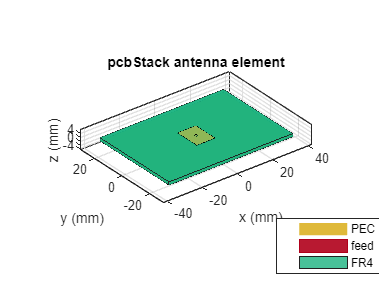

figure
show(pb1)

Below is the mesh used to model the antenna. The triangles are used to discretize the metal regions of the patch, and tetrahedra are used to discretize the volume of the dielectric substrate in the patch. These are indicated by the colors yellow and green respectively

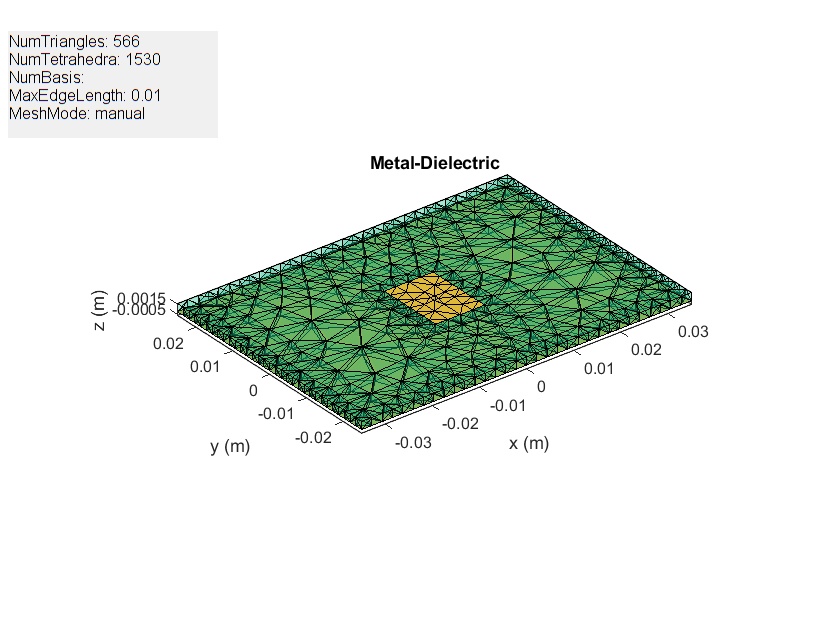

figure
mesh(pb1,MaxEdgeLength=0.01,MinEdgeLength=0.003)

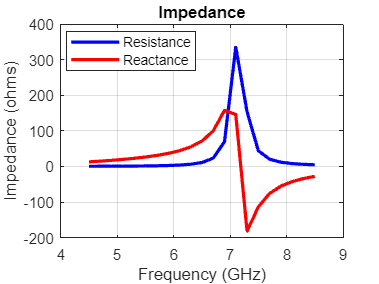

figure
impedance(pb1,linspace(4.5e9,8.5e9,21))

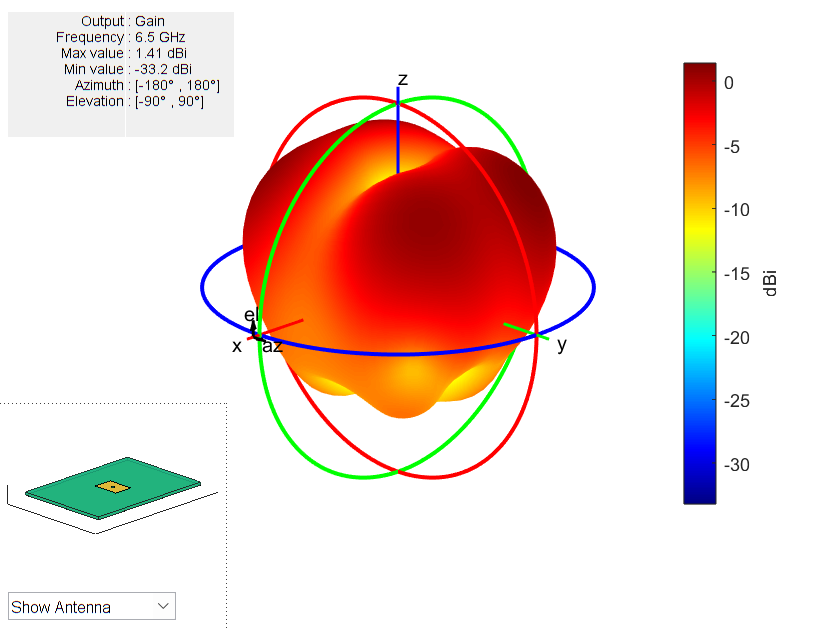

figure
pattern(pb1, freq)

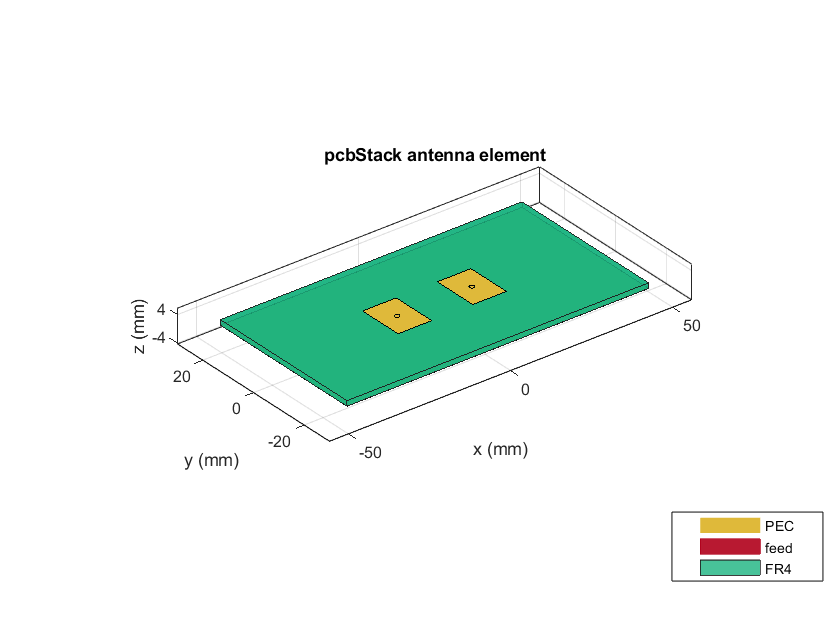

pcbArr = array(pb1,"linear",NumElements=2,ElementSpacing=l0/2); 
show(pcbArr)

Below is the mesh used to model the antenna. The triangles are used to discretize the metal regions of the patch, and tetrahedra are used to discretize the volume of the dielectric substrate in the patch. These are indicated by the colors yellow and green respectively

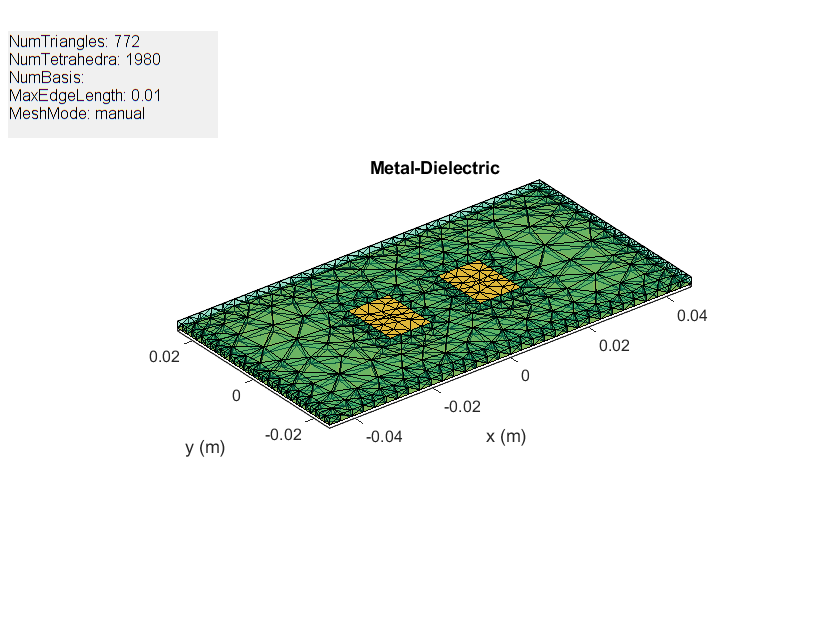

figure
mesh(pcbArr,MaxEdgeLength=0.01,MinEdgeLength=0.003)

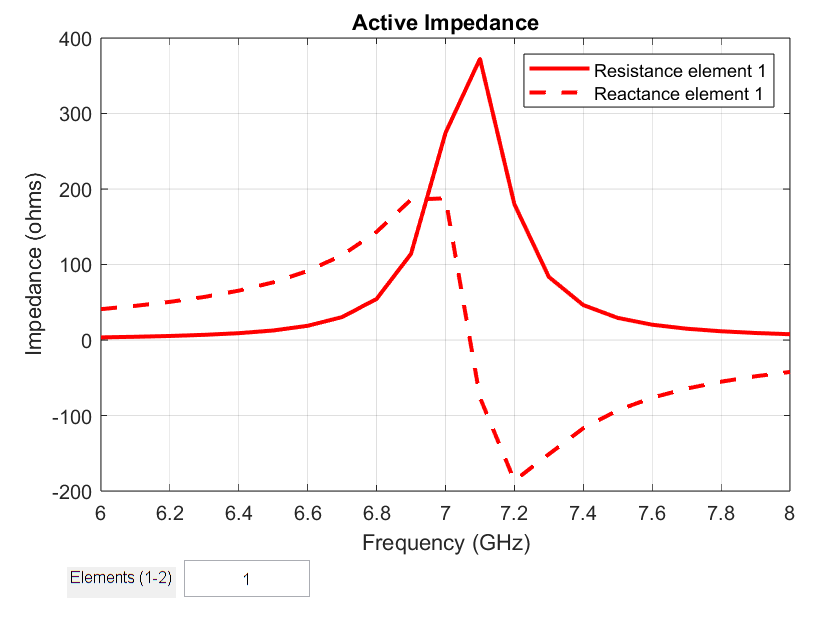

figure
impedance(pcbArr,linspace(6e9,8e9,21))

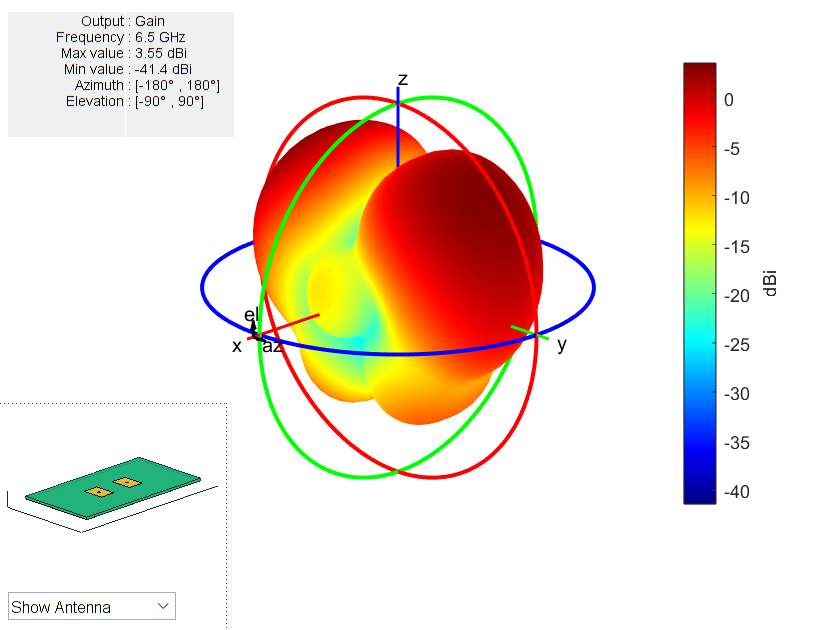

figure
pattern(pcbArr, freq)

## Make Dataset

elevationAngles = -90:90;
azimuthAngle = 90;

patternData = patternAzimuth(pcbArr, freq, elevationAngles, Azimuth=azimuthAngle);

% Create an array where column 1 is the angle and column 2 is the gain
resultArray = [elevationAngles' patternData'];

% Display the resulting array
disp(resultArray);

  -90.0000  -41.4257
  -89.0000  -28.3783
  -88.0000  -23.3129
  -87.0000  -20.1536
  -86.0000  -17.8674
  -85.0000  -16.0869
  -84.0000  -14.6388
  -83.0000  -13.4275
  -82.0000  -12.3946
  -81.0000  -11.5019
  -80.0000  -10.7229
  -79.0000  -10.0386
  -78.0000   -9.4350
  -77.0000   -8.9012
  -76.0000   -8.4289
  -75.0000   -8.0114
  -74.0000   -7.6432
  -73.0000   -7.3200
  -72.0000   -7.0382
  -71.0000   -6.7947
  -70.0000   -6.5869
  -69.0000   -6.4127
  -68.0000   -6.2701
  -67.0000   -6.1576
  -66.0000   -6.0738
  -65.0000   -6.0174
  -64.0000   -5.9873
  -63.0000   -5.9826
  -62.0000   -6.0023
  -61.0000   -6.0456
  -60.0000   -6.1117
  -59.0000   -6.1997
  -58.0000   -6.3089
  -57.0000   -6.4383
  -56.0000   -6.5871
  -55.0000   -6.7541
  -54.0000   -6.9380
  -53.0000   -7.1373
  -52.0000   -7.3502
  -51.0000   -7.5745
  -50.0000   -7.8075
  -49.0000   -8.0459
  -48.0000   -8.2861
  -47.0000   -8.5234
  -46.0000   -8.7525
  -45.0000   -8.9677
  -44.0000   -9.1626
  -43.0000   

writematrix(resultArray, 'antenna_gain_dataset.csv');